clear
syms z a

f1= (z^2-1)/(z-1);
limit(f1,z,1)

$$ans = 2$$


f2=(z^2+1)/(z-2i);
limit(f2,z,inf)

$$ans = \infty +2\,\mathrm{i}$$


f3=z/(z+1);
limit(f3,z,a);
subs(ans,a,1+1i)

$$ans = \frac{3}{5}+\frac{1}{5}\,\mathrm{i}$$

%%koshi reimanas
clear
syms z x y real

w=z^3-1i;
w=expand(subs(w,z,x+1i*y));
w=collect(w,1i);
u=real(w);
v=imag(w);
du_dx=diff(u,x);
du_dy=diff(u,y);
dv_dx=diff(v,x);
dv_dy=diff(v,y);
if(du_dx==dv_dy) && (du_dy==- dv_dx)
    fprintf('tenkina')
    isv=du_dx+1i*dv_dx
else 
    fprintf('netenkina')
end

tenkina

$$isv = 3\,x^{2}+6\,x\,y\,\mathrm{i}-3\,y^{2}$$

clear
syms k b x
z1=0;
z2=1+1i;

%y=k*x+b;

[k,b]=solve(imag(z1)==k*real(z1)+b, ...
            imag(z2)==k*real(z2)+b, k,b);
y=k*x+b

$$y = x$$


z=x+1i*y;
f=1+1i-2*conj(z);
dz=diff(z,x);

integralas=int(f*dz,x,real(z1),real(z2))

$$integralas = -2+2\,\mathrm{i}$$

clear
syms z

int(3i-z*conj(z),z,-1i,1i)

$$ans = -6-\frac{2}{3}\,\mathrm{i}$$

clear
syms z

x1=-1;
x2=-2;
y1=1;
y2=4;

z1=complex(x1,y1);
z2=complex(x2,y2);

f=z;
int(f,z,z1,z2);

clear
syms z

z1=complex(3,2);
z2=complex(4,4);
z3=complex(3,3);

f=z+z3;

int(f,z,z1,z2);

%%Rezidumai
clear
syms z

f=(z+2i)/(z*(z-1)^2);

[sk,var]=numden(f);
[yp_tsk]=solve(var==0,z);
%nesikartoja
z1=yp_tsk(1);
Rez_z1=limit(f*(z-z1),z,z1)

$$Rez\_z1 = 2\,\mathrm{i}$$

%kartotinumas
z2=yp_tsk(2);
k=2;
isv=diff(f*(z-z2)^k,z,k-1);
Rez_z2=limit(isv/factorial(k-1),z,z2);

$$Rez\_z2 = -2\,\mathrm{i}$$

clear
syms z a

f=cos(z)/(z^3+z);
[sk,var]=numden(f);
[yp_tsk]=solve(var==0,z);

var_sk=prod(factor(var,'FactorMode','full'))

$$var\_sk = z\,\left(z-\mathrm{i}\right)\,\left(z+\mathrm{i}\right)$$

f=sk/var_sk

$$f = \frac{\cos\left(z\right)}{z\,\left(z-\mathrm{i}\right)\,\left(z+\mathrm{i}\right)}$$


z2=yp_tsk(2);
Rez_z2=limit(f*(z-z2),z,a)

$$Rez\_z2 = \frac{\cos\left(a\right)}{a\,\left(a-\mathrm{i}\right)}$$

subs(Rez_z2,a,-1i)

$$ans = -\frac{\cos\left(\mathrm{i}\right)}{2}$$

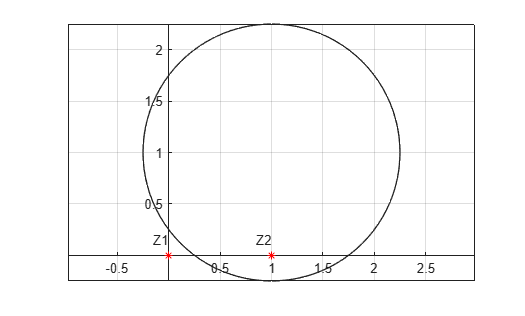

clear
syms z

f=2/(z^2*(z-1));
[sk,var]=numden(f);
[yp_tsk]=solve(var==0,z);

%|z-z0|=r
%|z-1-i|=5/4
%|z-(1+i)|=5/4

z0=1+1i;
r=5/4;
C=[real(z0) imag(z0)];

pos=[C-r 2*r 2*r];
x=real(yp_tsk);
y=imag(yp_tsk);

plot(x,y,'r*')
rectangle('Position',pos,'Curvature',[1 1])
axis equal
g=gca;
g.XAxisLocation='origin';
g.YAxisLocation='origin';
grid on

text(real(yp_tsk(1))-0.15,imag(yp_tsk(1))+0.15, 'Z1');
text(real(yp_tsk(3))-0.15,imag(yp_tsk(3))+0.15, 'Z2');


z2=yp_tsk(3);
Rez_z2=limit(f*(z-z2),z,z2);
integralas=2*pi*1i*Rez_z2

$$integralas = 4\,\pi \,\mathrm{i}$$